# Laboratory 2 (week 3)

Loading the data and plotting it

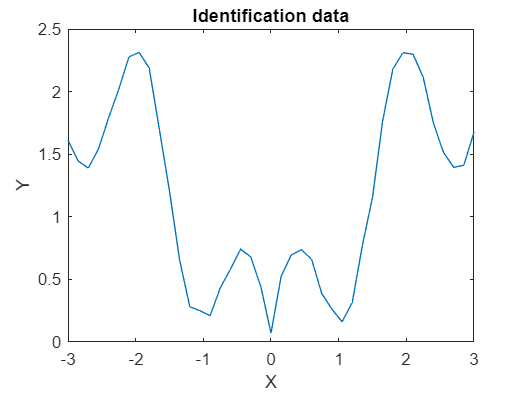

clear variables;

s = load("lab2_11.mat");

plot(s.id.X, s.id.Y); hold on; hold off;
title("Identification data");
xlabel("X"); ylabel("Y");

Find the model (model fit).

n = 9;
phi = [];
row = @(x)([1 x.^1 x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8]);

for i = 1:length(s.id.X)
    phi = [phi; row(i)];
end

y = s.id.Y.';
theta = phi\y;
y_cap = phi*theta;
mse = 1/length(s.id.Y)*sum((y_cap-y).^2)

mse = 0.0447

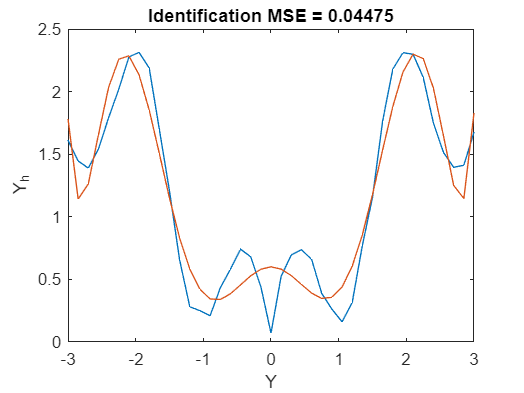


plot(s.id.X,y,s.id.X,y_cap);
title("Identification MSE = " + string(mse));
xlabel("Y"); ylabel("Y_h");

Validate model.

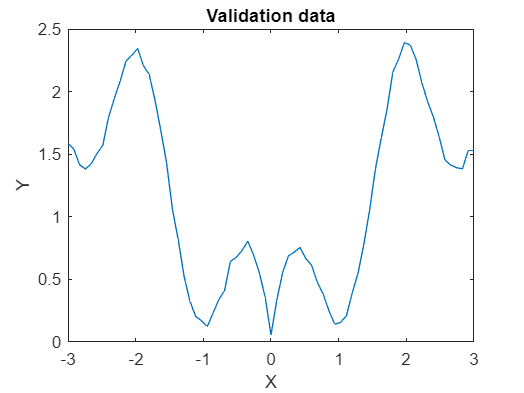

plot(s.val.X, s.val.Y); hold on; hold off;
title("Validation data");
xlabel("X"); ylabel("Y");


phi_val = [];

for i = 1:length(s.val.X)
    phi_val = [phi_val; row(i)];
end

y_val = s.val.Y.';
theta = phi_val\y_val;

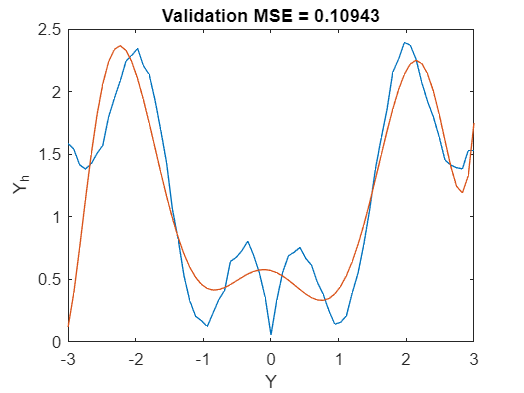

y_val_cap = phi_val*theta;
mse = 1/length(s.val.Y)*sum((y_val_cap-y_val).^2);

plot(s.val.X,y_val,s.val.X,y_val_cap);
title("Validation MSE = " + string(mse));
xlabel("Y"); ylabel("Y_h");